Controllo se è rimasta aperta la porta seriale

if( exist('STM32_ser') );
    delete(STM32_ser);
    clear STM32_ser;
end

Connetto alla seriale

porte_libere = serialportlist("available")

porte_libere = "COM8"

STM32_ser = serialport(porte_libere(end), 9600, Timeout=5);
configureTerminator(STM32_ser,"CR")
STM32_ser.flush;

Richiedo il buffer tramite char 'e'

STM32_ser.write('e','char');
vettore=read(STM32_ser,1000,'uint32');
length(vettore)

ans = 1000

Impostazione ordine di grandezza corretto

for i=1:length(vettore);
    vettore(i) = vettore(i)/1000;
end

h=plot(vettore, '--pentagram');

fprintf('Temperatura Media: %f°C',mean(vettore))

Temperatura Media: 37.476335°C

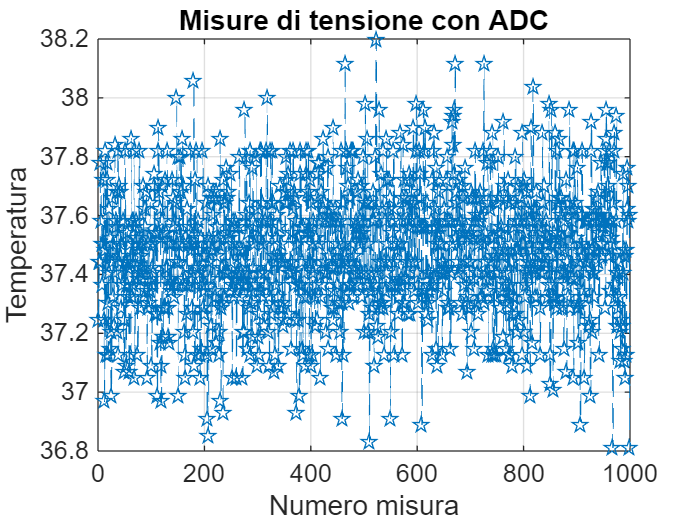


title('Misure di tensione con ADC');
ylabel("Temperatura");
xlabel('Numero misura');
box on
grid on